**方程式求解**

1. 方程和方程组的解析解

% 声明符号变量
syms a b c x;
solve(a*x^2 + b*x + c, x) % 对x求解

$$ans = \left(\begin{array}{c} -\frac{b+\sqrt{b^{2}-4\,a\,c}}{2\,a}\\ -\frac{b-\sqrt{b^{2}-4\,a\,c}}{2\,a} \end{array}\right)$$

ans =
Empty sym: 0-by-1


syms x;
y = 2*x - x^2 - exp(-x);
solve(y, x)

$$ans = 0.41640296239270530567959997618172$$

syms a b x y;
y1 = x + b*y - 5;
y2 = a*x - y - x;
res = solve([y1, y2], [x, y]);
res.x

$$ans = \frac{5}{a\,b-b+1}$$

res.y

$$ans = \frac{5\,\left(a-1\right)}{a\,b-b+1}$$

2. 方程和方程组的数值解

f = @(x)2*x-x^2-exp(-x);
res = fsolve(f, 0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


res

res = 0.4164


a=3;
b=5;
f = @(x)func(x, a, b);

res = fsolve(f, [0,0]);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


res

res =     0.4545    0.9091


3. 常微分方程和方程组的解析解

syms y(x);
dsolve(diff(y) == 2*x, y(0)==1)

$$ans = x^{2}+1$$

syms y(x) mu;
equ = diff(y, 2) == mu*diff(y)+y;
cond1 = y(0)==1;
dy = diff(y);
cond2 = dy(0)==0;

dsolve(equ, cond1, cond2)

$$ans = \frac{{\mathrm{e}}^{x\,\left(\frac{\mu }{2}-\frac{\sqrt{\mu^{2}+4}}{2}\right)}\,\left(\mu +\sqrt{\mu^{2}+4}\right)}{2\,\sqrt{\mu^{2}+4}}-\frac{{\mathrm{e}}^{x\,\left(\frac{\mu }{2}+\frac{\sqrt{\mu^{2}+4}}{2}\right)}\,\left(\mu -\sqrt{\mu^{2}+4}\right)}{2\,\sqrt{\mu^{2}+4}}$$

4. 常微分方程和方程组的数值解

**MATLAB求解的标准形式: **$M\left(x,y\right)*y\prime =F\left(x,y\right)$

eg 1:  $y\prime =2x\;\;\mathrm{初值y}\left(0\right)=10\;\;\mathrm{积分区间}\left\lbrack 0,10\right\rbrack$

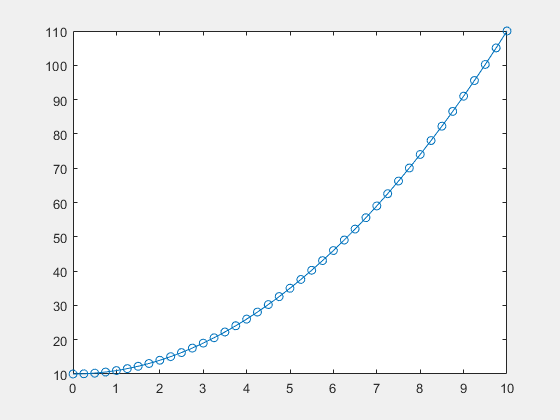

f = @(x, y)2*x;
tspan = [0, 10];
y0 = 10;
ode45(f, tspan, y0)

eg 2: $y\prime \prime =\mu \left(1-y^2 \right)y\prime +y$初值y(0)=1, y'(0)=0，积分区间为[0, 20]

转化为y1=y, y2=y'


$$\left\lbrace \begin{array}{ll}
{y_1 }^{\prime } =y_2  & \\
{y_2 }^{\prime } =\mu \left(1-{y_1 }^2 \right)y_2 +y_1  & 
\end{array}\right.$$


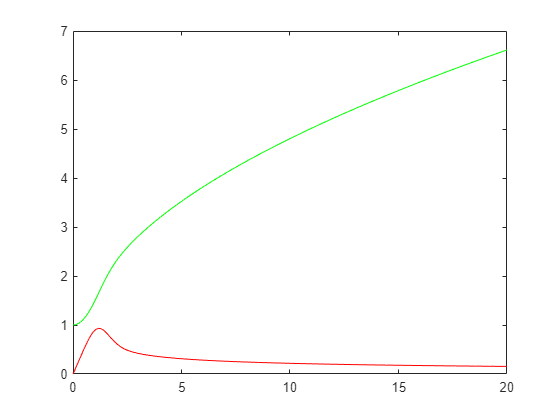

mu = 1;
f = @(x, y)func1(y, mu);
tspan = [0,20];
y0 = [1, 0];
[x,y] = ode45(f, tspan, y0);
plot(x, y(:,1),'g', x, y(:,2),'r');

function y = func(x, a, b)
	y(1) = x(1)+b*x(2)-5;
	y(2) = a*x(1)-x(2)-x(1);
end

function ydot = func1(y, mu)
	ydot = [y(2); mu*(1-y(1)^2)*y(2)+y(1)];
end